%Ejercicio 1

num = [0.25 1 1];
den = [0.5 0];
H = tf (num, den);
H = zpk(H)

H =
 
  0.5 (s+2)^2
  -----------
       s
 
Continuous-time zero/pole/gain model.



num = [1];
den = [1 2 2];
C = tf (num, den);
G = feedback ((H*C),1);
L = minreal(tf(G))

L =
 
     0.5 s^2 + 2 s + 2
  -----------------------
  s^3 + 2.5 s^2 + 4 s + 2
 
Continuous-time transfer function.



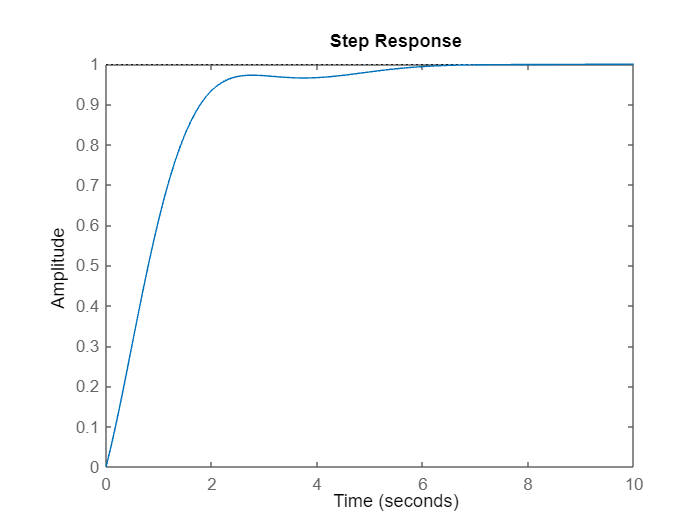

figure()
step(L, 10)